**Student Name:** Naman Shah

**Last 4 Digits of RUID:** 8939

**Section:** C1

**Math 250 MATALB Assignment:** 4

rand('seed', 8939)

**Question 1**. Visualizing the Column Space

A = rmat(3,2)

A =      8     6
     2     5
     1     8


A =      8     6
     2     5
     1     8


rank(A)

ans = 2

(1)(a)

u = A(:,1)

u =      8
     2
     1


v = A(:,2)

v =      6
     5
     8


[s,t] = meshgrid((-1:0.1:1), (-1:0.1:1));
X = s*u(1)+t*v(1); Y = s*u(2)+t*v(2); Z = s*u(3)+t*v(3);
surf(X,Y,Z); axis square; colormap hot, hold on

(1)(b)

b = rvect(3)

b =      6
     9
     7


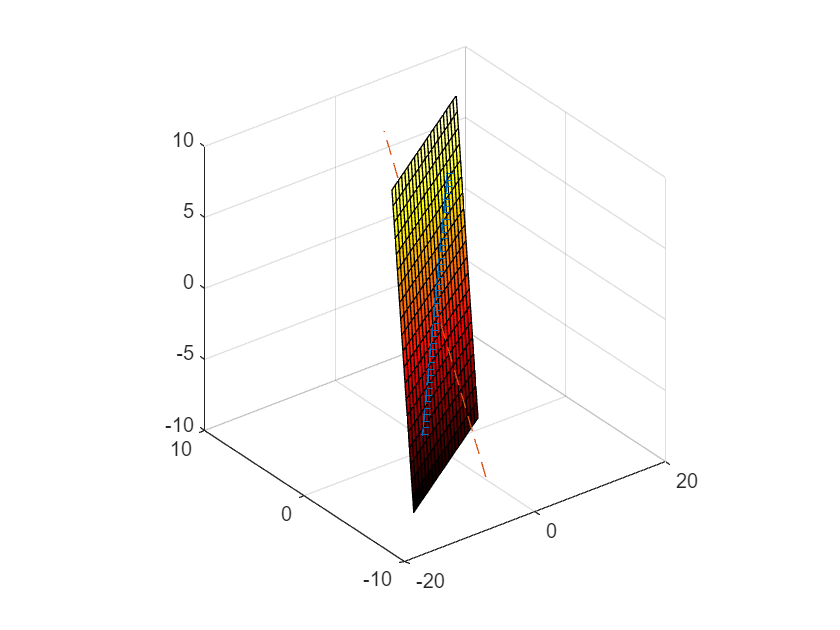

r = -1:0.05:1;
plot3(r*b(1),r*b(2),r*b(3), '--')

No, it is not in the column span as b does not lie inside col(A) graphically.

(1)(c)

The graph represents the column space of A which represents all linear combinations of A.

Because the vector b intersects Col(A), you can find a vector such that Ax = b. So yes.

z = rand(2,1)

z =     0.6041
    0.6322


c = A*z

c =     8.6258
    4.3692
    5.6617


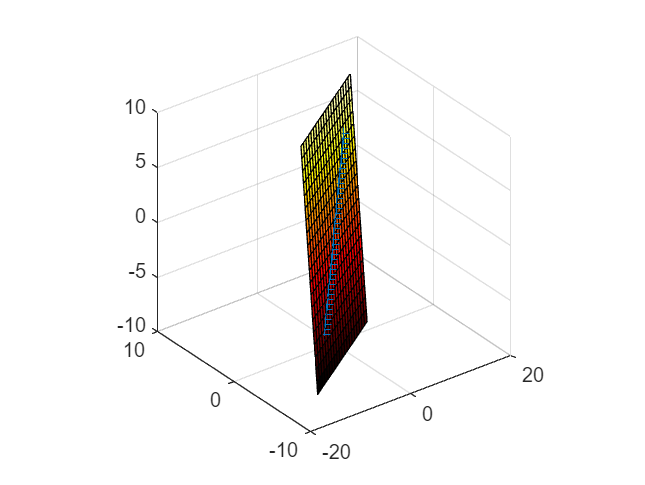

figure, surf(X,Y,Z); axis square; colormap hot, hold on
plot3(r*c(1),r*c(2),r*c(3), '+')

Yes, the entire line Span(c) is contained in Col(A).

**Question 2**. Visualizing the Column Space

B = rmat(3,3)

A =      4     0     9
     4     4     5
     7     1     9


B =      4     0     9
     4     4     5
     7     1     9


rank(B)

ans = 3

A = [B(:,1), B(:,2), 2*B(:,1) + 3*B(:,2), 4*B(:,1) - 5*B(:,2), B(:,3)],

A =      4     0     8    16     9
     4     4    20    -4     5
     7     1    17    23     9


R = rref(A)

R =      1     0     2     4     0
     0     1     3    -5     0
     0     0     0     0     1


(2)(a)

According to the column correspondence theorem, if col j of the rref(A) matrix R is a linear combination of the other columns of R, col j of A is a linear combination of the corresponding columns of A using the same coefficients. As they are A's pivot columns, columns 1, 2, and 5 are linearly independent. 

Given that they are a linear combination of the other columns in R, columns 3 and 4 are said to be linearly dependent. More specifically, columns 1 and 2 may be combined linearly to form columns 3 and 4. 

(2)(b)

The free variables are x3 and x4 since they are the linearly dependent columns and therefore contain free variables. Since the nullity of A is 2, the dim V = 2.

(2)(c)

N = nulbasis(A)

N =     -2    -4
    -3     5
     1     0
     0     1
     0     0


v1 = N(:,1)

v1 =     -2
    -3
     1
     0
     0


v2 = N(:,2)

v2 =     -4
     5
     0
     1
     0


The third component of v1 is 1, and the fourth and fifth components of v1 are zeroes.

The fourth component of v2 is 1, and the third and fifth components of v2 are zeroes.

Yes, v1 and v2 are in N

(2)(d)

s = rand(1)

s = 0.3885

t = rand(1)

t = 0.7702

x = s*v1+t*v2

x =    -3.8577
    2.6857
    0.3885
    0.7702
         0


The reason why x satisfies Ax=0 and Rx=0 is because R = rref(A), and thus a solution for Rx=0 would also carry forward for Ax=0. We also know x is a linear combination of v1 and v2, which are columns of the null spcae of A, which by definition is the solution set of Ax=0.

A*x

ans =      0
     0
     0


R*x

ans =      0
     0
     0


Yes, they are both zero vectors.

**Question 3**. Visualizing the Column Space

(3)(a)

A = rmat(5, 3)

A =      8     7     2
     8     6     6
     0     3     8
     2     5     5
     0     5     9


A =      8     7     2
     8     6     6
     0     3     8
     2     5     5
     0     5     9


R = rref(A)

R =      1     0     0
     0     1     0
     0     0     1
     0     0     0
     0     0     0


rank(A(:,1:3))

ans = 3

There exist certain vectors b within R^5 such that the equation Ax=b does not have a particular solution because in R there are more rows than pivot columns (to be consistent, cannot have a zero row). This is also because we cannot inverse to get a solution. This is an overdetermined system.

b = rmat(5,1)

A =      2
     6
     1
     2
     6


b =      2
     6
     1
     2
     6


xp = partic(A, b)


xp =

     []



b = rand(1)*A(:,1) + rand(1)*A(:,2) + rand(1)*A(:,3)

b =     9.1768
   11.3122
    6.2982
    6.4704
    7.7443


xp = partic(A, b)

xp =     0.6335
    0.4055
    0.6352


A*xp

ans =     9.1768
   11.3122
    6.2982
    6.4704
    7.7443


b

b =     9.1768
   11.3122
    6.2982
    6.4704
    7.7443


Yes, A*xp = b.

Since the vector b is a linear combination of the column vectors of A, the special form of b guarantees that there is a solution for Ax=b such that it must be in the span and therefore will always be consistent with the overdetermined system.

(3)(b)

A = rmat(3,5)

A =      1     8     1     9     6
     3     7     6     8     7
     2     7     1     3     1


A =      1     8     1     9     6
     3     7     6     8     7
     2     7     1     3     1


R = rref(A)

R =     1.0000         0         0   -4.5455   -4.0000
         0    1.0000         0    1.4545    1.0000
         0         0    1.0000    1.9091    2.0000


rank(A(:,1:3))

ans = 3

We know that the number of rows of A = rankA, so Ax = b must have at least one solution, making it consistent, for each b in R ^ m since A*x can form a linearly combination for every vector in R ^ m.

b = rmat(3,1)

A =      4
     7
     8


b =      4
     7
     8


xp = partic(A, b)

xp =     4.1136
    0.1136
   -1.0227
         0
         0


We knoww that A has 5 columns and vector x has 5 rows, indicating there are 5 variables. Since rankA=3 & the number of columns of A = 5, nullity is 2 which corresponds to the 2 free variables of rows four and five of xp. 

A*xp

ans =     4.0000
    7.0000
    8.0000


b

b =      4
     7
     8


Yes, A*xp = b.

**Question 4**. General Solution to Ax=b

N = nulbasis(A)

N =     4.5455    4.0000
   -1.4545   -1.0000
   -1.9091   -2.0000
    1.0000         0
         0    1.0000


v1 = N(:,1)

v1 =     4.5455
   -1.4545
   -1.9091
    1.0000
         0


v2 = N(:,2)

v2 =      4
    -1
    -2
     0
     1


x = xp + rand(1)*v1 + rand(1)*v2 

x =    11.0544
   -1.8682
   -4.2112
    0.7753
    0.8542


A*x

ans =     4.0000
    7.0000
    8.0000


b

b =      4
     7
     8


Yes, Ax = b.

(4)(b)

x = [x1, x2, x3, -9, 8] ^ T

x = xp - 9*v1 + 8*v2

x =    -4.7955
    5.2045
    0.1591
   -9.0000
    8.0000


A*x

ans =     4.0000
    7.0000
    8.0000


b

b =      4
     7
     8


Yes, Ax = b.

**Question 5**. General Solution to Ax=b

A = [0.3,0;0.14,0;0.56,1]

A =     0.3000         0
    0.1400         0
    0.5600    1.0000


B = [0.5,0,0;0.5,1,0.6;0,0,0.4]

B =     0.5000         0         0
    0.5000    1.0000    0.6000
         0         0    0.4000


C = [1,0.3,0;0,0.2,0;0,0.35,0.7;0,0.15,0.3]

C =     1.0000    0.3000         0
         0    0.2000         0
         0    0.3500    0.7000
         0    0.1500    0.3000


M = C*B*A

M =     0.3378    0.1800
    0.1252    0.1200
    0.3759    0.4900
    0.1611    0.2100


(5)(a)

x = 1000*rvect(2)

x =         6000
        9000


y = A*x

y = 1.0e+04 *

    0.1800
    0.0840
    1.2360


z = B*y

z =          900
        9156
        4944


w = C*z

w = 4×1
1.0e+03 *

    3.6468
    1.8312
    6.6654
    2.8566


[1 1]*x

ans = 15000

[1 1 1]*y

ans = 15000

[1 1 1 1]*w

ans = 15000

The number of automobiles entering or leaving certain lanes is shown by each response. The total number of autos coming through the x1 and x2 paths is therefore equal to [1 1]*x. In a similar manner, the total number of autos on the y route is represented as [1 1 1]*y. Since each response indicates the entire number of automobiles in the system on all possible pathways, they are all identical. The total number of vehicles on all pathways will match the number of vehicles that were added to the system at the beginning. Meaning,  all values would be the same.

(5)(b)

y = [270; 126; 704]

y = 3×1
   270
   126
   704


xp = partic(A, y)

xp = 2×1
   900
   200


A*xp

ans = 3×1
  270.0000
  126.0000
  704.0000


This is solved as A*xp = y; the approach utilized in question 4 offers a general solution, but the method employed here in (5)(b) is workable for a particle solution of A*x=b, or in this case, A*x=y. The entering traffic flow vector, x, is identified in this situation. 

(5)(c)

w = [100; 200; 300; 400]

w = 4×1
   100
   200
   300
   400


xp = partic(M, w)


xp =

     []



rref([M w])

ans = 4×3
     1     0     0
     0     1     0
     0     0     1
     0     0     0


The Matrix formed with [M w] is not consistent with w = M*w, because there is no such solution where W is an output traffic vector. This is why we got an empty vector as the output for xp.